# Solving Differential Equations

## Forward Euler

The forward Euler method of solving differential equations is extremely simple. Given a vector consisting of $x$ and all the derivatives of $y$, we can use a linear approximation to update the values of each over a small step size $h$. Specifically, given an implicit expression $y^{(m)} = f(x, y, y', \dots, y^{(m - 1)})$ and a set of initial conditions $y(x_0), y'(x_0), ..., y^{(m - 1)}(x_0)$ for some $x = x_0$, we can write the following vector:


$$\mathbf x_0 = \pmatrix{ x_0 \cr y(x_0) \cr y'(x_0) \cr \vdots \cr y^{(m-1)}(x_0)}$$


We can then approximate the value of each parameter at $x = x_1 = x_0 + h$ by linearly approximating each$y$ and its derivatives


$$\mathbf x_1 = \pmatrix{ x_0 + h \cr y(x_0) + hy'(x_0) \cr y'(x_0) + hy''(x_0) \cr \vdots \cr y^{(m - 1)}(x_0) + hf(x, y, y', \dots, y^{(m - 1)})}$$


Using these values we can then estimate each function at $x = x_2 = x_1 + h$ and so on. For information on the implementation, see forwardEuler.m.

Here are some examples of this method in action:

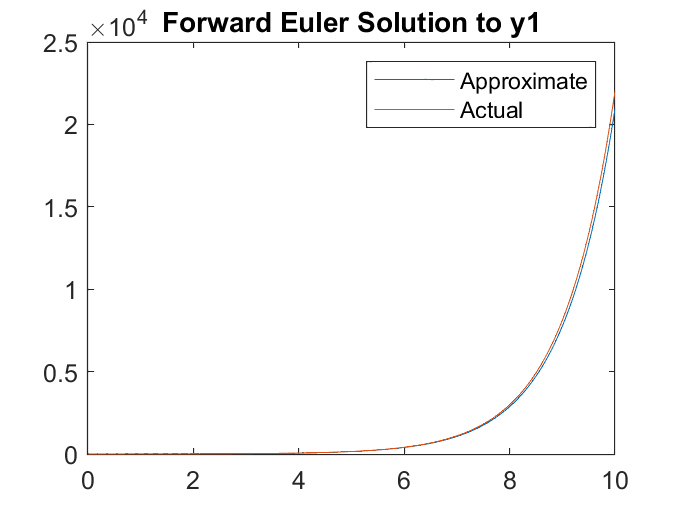

% example calculation with y' = y - x, y(0) = 2
y = @(x, y0) y0 - x;
sol1 = forwardEuler(y, [0; 2], 0.01, 1000);

% plotting against actual solution y = e^x + x + 1
figure
plot(sol1(1, :), sol1(2, :))
hold on
x1 = linspace(0, 10, 1000);
y1 = exp(x1) + x1 + 1;
plot(x1, y1)
title("Forward Euler Solution to y1")
legend("Approximate", "Actual");
hold off

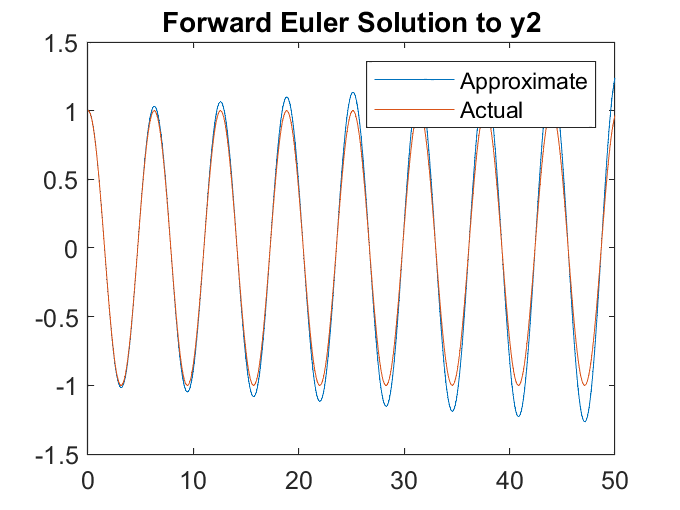


% example calculation with z'' = -z, z(0) = 1, z'(0) = 0
z = @(x, y0, y1) -y0;
sol2 = forwardEuler(z, [0; 1; 0], 0.01, 5000);

% plotting against actual solution y = cos(x)
figure
plot(sol2(1, :), sol2(2, :))
hold on
x2 = linspace(0, 50, 1000);
y2 = cos(x2);
plot(x2, y2)
title("Forward Euler Solution to y2")
legend("Approximate", "Actual");
hold off

## Backward Euler

The backward Euler method involves solving for the value of $y$ using the derivative at a later point. Specifically, given the implicit equation $y' = f(x, y)$, we have that


$$y(x_{n+1}) - y(x_n) = \int_{x_n} ^{x_{n+1}} f(x, y(x)) \; dx $$


Using a right Riemann sum with a single rectangle, we have that


$$y(x_{n+1}) - y(x_n) \approx hf(x_{n+1}, y(x_{n+1}))$$


By solving for $y(x_{n+1})$ using Newton-Raphson or any other equation solving method, we can choose the next point in a more stable fashion.

For these purposes, backward Euler has only been implemented for first-order ODEs.

Here is an example of the algorithm in action.

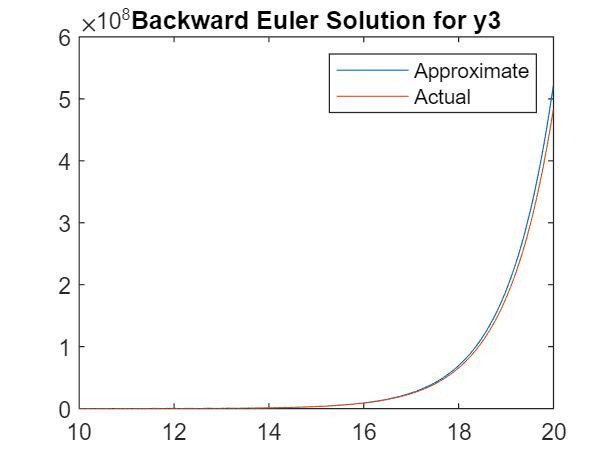

% backward euler for y' = y - x, y(10) = e^10 + 10 + 1
sol3 = backwardEuler(y, [10; exp(10) + 10 + 1], 0.02, 500);
figure
plot(sol3(1, :), sol3(2, :))
hold on
x3 = linspace(10, 20, 1000);
y3 = exp(x3) + x3 + 1;
plot(x3, y3)
title("Backward Euler Solution for y3")
legend("Approximate", "Actual");
hold off

## Runge-Kutta

The Runge-Kutta methods are a family of differential equation solving methods. In this example, we have the RK4 method, which uses a weighted average of four different slopes between two points separated by a time step to more accurately compute the next point. Specifically, we calculate the following four slopes for the expression $y' = f(x, y)$:


$$k_1 = f(x_n, y_n)$$



$$k_2 = f\left(x_n + \frac h2, y_n + h\frac{k_1}{2}\right)$$



$$k_3 = f\left(x_n + \frac h2, y_n + h\frac{k_2}{2}\right)$$



$$k_4 = f(x_n + h, y_n + hk_3)$$


We then average these slopes accordingly to linearly predict the next point:


$$y_{n+1} = \frac{h}{6}(k_1 + 2k_2 + 2k_3 + k_4)$$



$$x_{n+1} = x_n + h$$


An example of this method in action is shown below:

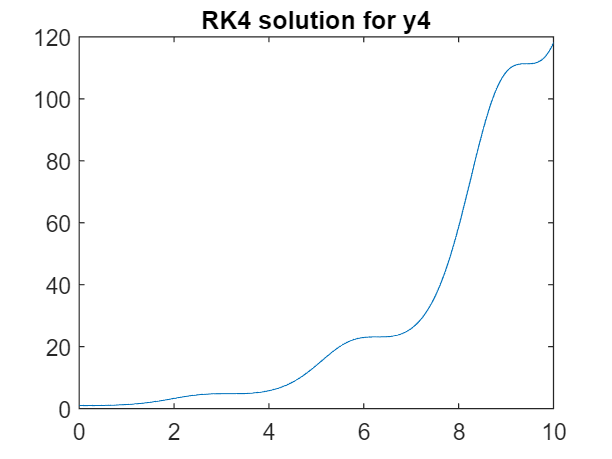

% solving y' = y sin^2(x) using RK4
y4 = @(x, y0) sin(x)^2 * y0;
sol = rk4(y4, [0; 1], 0.01, 1000);

figure
plot(sol(1, :), sol(2, :))
title("RK4 solution for y4")